# **Ex 2.12**

## **Descrizione:**

Pulizia

clear; clc; close('all');

Importazione dei dati con assegnazioni alle variabili. Si preferisce questa funzione per la sua semplicità di utilizzo nell'assegnazione alle variabili.

 A = importdata('../data/velocityy.dat');
 t = A(:,1);
 v = A(:,2);

`Creazione delle variabili di ausilio allo script. La variabile `dimT` non è essenziale, ma permette la modifica dei dati nel file velocityy.dat senza dover poi stravolgere la funzione.`

 dimT = length(t);
 y = zeros( dimT, 1 );
dv = zeros( dimT, 1 );

Si genera il primo grafico con i dati del file.

subplot(3,1,1)
plot(t,v);
title('v(t)'); xlabel('t'); ylabel('v');

Tenendo conto della formula, con un ciclo `for `calcolo `y(t). `

  y(1) = 0;
for ii = 2:dimT
     tmp1 = t(ii)-t(ii-1);
    y(ii) = y(ii-1) + v(ii-1) * (tmp1);
end; clear('ii', 'tmp1');

Il testo è risultato un po' criptico. Ho calcolato la derivata della velocità $\frac{\textrm{d}}{\textrm{d}t}v$

 dv(1) = 0;
for jj = 2:dimT
    tmp1 = ( y(jj) - y(jj-1) );
    tmp2 = ( t(jj) - t(jj-1) );
    dv(jj) = ( tmp1 / tmp2 ) / tmp2;
end; clear('jj', 'tmp1', 'tmp2');

Metto a grafico `y(t)`

subplot(3, 1, 2);
plot(t, y);
title('y(t)'); xlabel('t'); ylabel('y');

e $\mathrm{dv}$

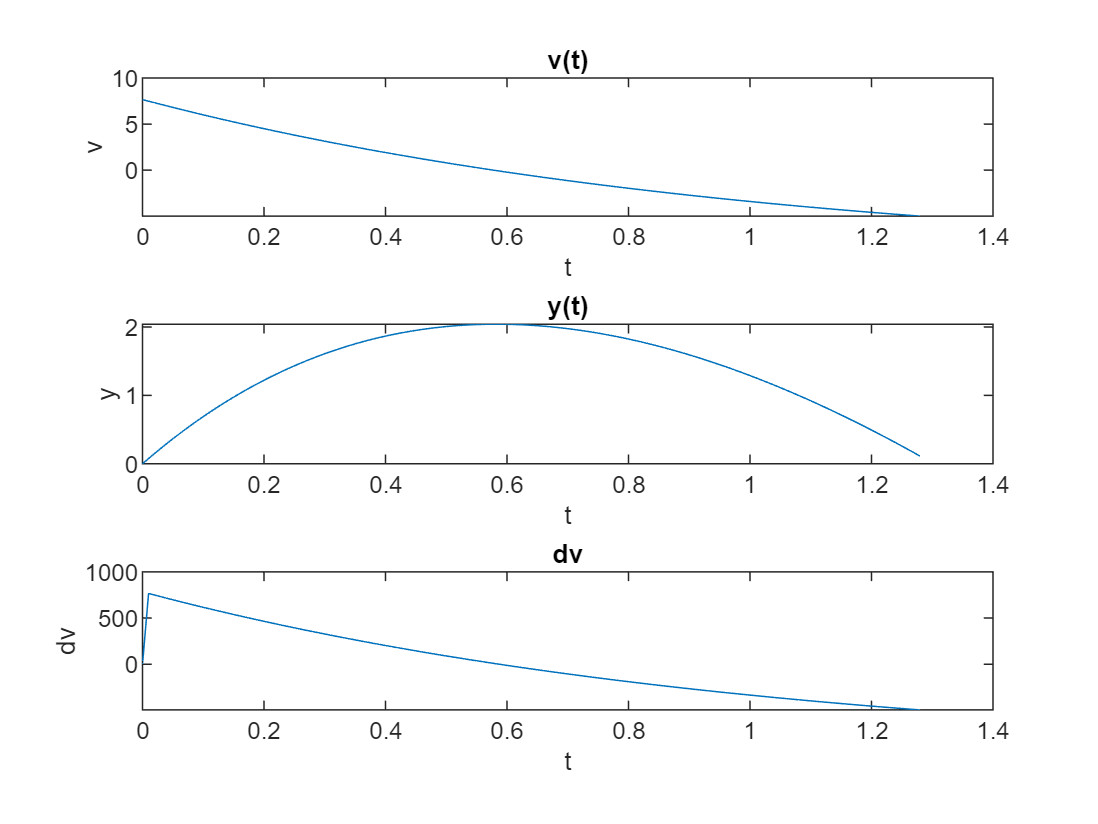

subplot(3, 1, 3);
plot(t, dv);
title('dv'); xlabel('t'); ylabel('dv');